####  Angular Momentum

load('net.mat')
load('test_data1_cell.mat');
load('test_data1.mat');

net = net;

% Setting up simulation parameters
start = 16;
numSimulations = 25;
data = test_data1_cell;
data11 = test_data1;

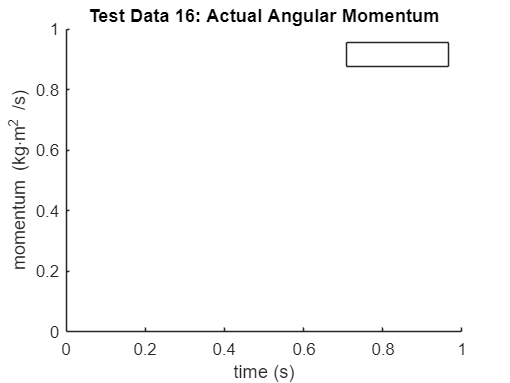

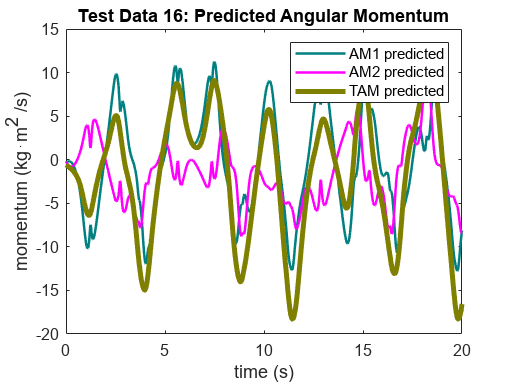

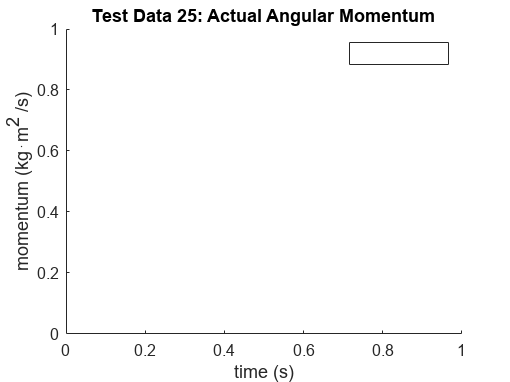

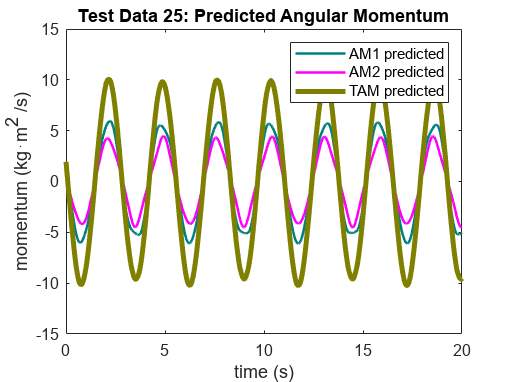

% Loop through the specified simulations
for i = [16 25]%start:numSimulations
    time = data{i, 1};
    theta1 = data{i, 2};
    theta2 = data{i, 3};
    omega1 = data{i, 4};
    omega2 = data{i, 5};
    x1 = data{i, 6};
    y1 = data{i, 7};
    x2 = data{i, 8};
    y2 = data{i, 9};

    % Transposing the data
    inputTime   = time';
    inputTheta1 = theta1';
    inputTheta2 = theta2';
    inputOmega1 = omega1';
    inputOmega2 = omega2';
    inputX1     = x1';
    inputY1     = y1';
    inputX2     = x2';
    inputY2     = y2';
    
    % Calculating actual angular momentum components and total angular momentum
    actual_am1 = m1 * L1^2 * data11(i).omega1 + m2 * L1^2 * data11(i).omega1+ m2 * L1 * L2 * data11(i).omega2 .* cos(data11(i).theta1 - data11(i).theta2);
    actual_am2 = m2 * L2^2 * data11(i).omega2 + m2 * L1 * L2 * data11(i).omega1 .* cos(data11(i).theta1 - data11(i).theta2);
    actual_tam = actual_am1 + actual_am2;


    % Making predictions using the neural network   
    predictedTime   = predict(net, {inputTime});
    predictedTheta1 = predict(net, {inputTheta1});
    predictedTheta2 = predict(net, {inputTheta2});
    predictedOmega1 = predict(net, {inputOmega1});
    predictedOmega2 = predict(net, {inputOmega2});
    predictedX1     = predict(net, {inputX1});
    predictedY1     = predict(net, {inputY1});
    predictedX2     = predict(net, {inputX2});
    predictedY2     = predict(net, {inputY2});

    % Converting predicted data to matrices
    newPredictedTime   = cell2mat(predictedTime);
    newPredictedTheta1 = cell2mat(predictedTheta1);
    newPredictedTheta2 = cell2mat(predictedTheta2);
    newPredictedOmega1 = cell2mat(predictedOmega1);
    newPredictedOmega2 = cell2mat(predictedOmega2);
    newPredictedX1     = cell2mat(predictedX1);
    newPredictedY1     = cell2mat(predictedY1);
    newPredictedX2     = cell2mat(predictedX2);
    newPredictedY2     = cell2mat(predictedY2);

    % Calculating predicted angular momentum components and total angular momentum
    predicted_am1 = m1 * L1^2 * newPredictedOmega1 + m2 * L1^2 * newPredictedOmega1 + m2 * L1 * L2 * newPredictedOmega2 .* cos(newPredictedTheta1 - newPredictedTheta2);
    predicted_am2 = m2 * L2^2 * newPredictedOmega2 + m2 * L1 * L2 * newPredictedOmega1 .* cos(newPredictedTheta1 - newPredictedTheta2);
    predicted_tam = predicted_am1 + predicted_am2;

     % Plotting actual total angular momentum
     figure;
      
    xlabel('time (s)');
    ylabel('momentum (kg⋅m^2 /s)');
    title(['Test Data ', num2str(i), ': Actual Angular Momentum']);
    legend('AM1 actual','AM2 actual','TAM actual'); 
    hold off; 


    

     % Plotting predicted total angular momentum 
     figure;
     plot(time, predicted_am1, 'Color', [0, 0.5, 0.5], 'LineWidth', 1.5);
     hold on;
     plot(time, predicted_am2, 'Color', 'magenta', 'LineWidth', 1.5);
     plot(time, predicted_tam, 'Color', [0.5, 0.5, 0], 'LineWidth', 3);
    xlabel('time (s)');
    ylabel('momentum (kg⋅m^2 /s)');
    title(['Test Data ', num2str(i), ': Predicted Angular Momentum']);
    legend('AM1 predicted','AM2 predicted','TAM predicted'); 
    hold off; 

    % Storing the current figure handle
    figHandles{i} = gcf;
end

% Saving all figures into a single MAT-file
save('DP_Conservation_of_angular_momentum_figures.mat', 'figHandles');

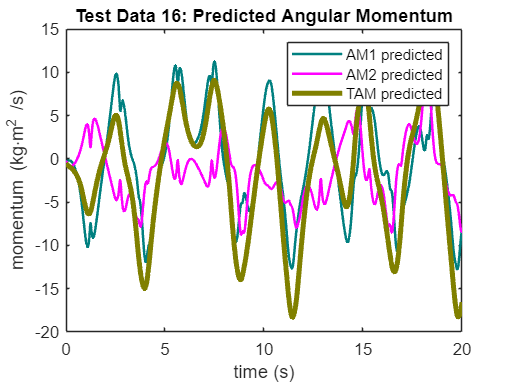

% To load the figures:
% 1. Loading the MAT-file
loadedData = load('DP_Conservation_of_angular_momentum_figures.mat');

% 2. Access the figure handles
loadedFigHandles = loadedData.figHandles;

% 3. Display the figures
for i = [16 25]%start:numSimulations
    figure(loadedFigHandles{i});
end